# **Graph Theory Reference Handout**

## **Definitions**

- **Graph**: A graph $G=\left(V,E\right)$ is a collection of vertices $V$ and edges $E$ connecting pairs of vertices.

- **Adjacency Matrix**: A square matrix where entry $A_{i,j}$ represents the number of edges connecting vertex $i$ to vertex$j$. In an undirected graph, this matrix is symmetric.

- **Incidence Matrix**: A matrix where rows represent vertices and columns represent edges. Each entry indicates whether a vertex is incident (connected) to a specific edge.

- **Degree of a Vertex**: The number of edges incident (i.e. connected) to a vertex. In an adjacency matrix, the degree is the sum of entries in the corresponding row.

- **Simple Graph**: A graph with no self-loops (edges connecting a vertex to itself) and no parallel edges (multiple edges between two vertices).

- **Cycle**: A closed path with no repeated vertices, except for the starting and ending vertex. A graph with at least one cycle contains a path that starts and ends at the same vertex without retracing any edges.

- **Connected Graph**: A graph is connected if a path exists between every pair of vertices.

- **Eulerian Graph**: A connected graph where every edge is traversed exactly once for any starting vertex back to itself (Eulerian circuit).

- **Tree**: A connected graph that contains no cycles.

- **Bipartite Graph**: A graph whose vertices can be divided into two disjoint sets $S_1$ and $S_2$ so every edge connects a vertex in $S_1$ to one in $S_2$. Vertices in the same group cannot be connected.

## **Theorems**

- **Theorem**: A connected graph is **Eulerian** if every vertex has an even degree.

## Examples

For each graph below, create a structure that contains the following fields:

- `vertices` (n x 1, integers): List of vertex index IDs

- `edges` (m x 2): A matrix where each row represents an edge connecting two vertices.

- `n` (integer): The number of vertices in the graph.

- `m` (integer): The number of edges in the graph.

- `adj_mat` (n x n double array): The adjacency matrix of the graph.

- `inc_mat` (n x m double array): The incidence matrix of the graph.

- `degrees` (n x 1, integers): List of each vertex degree.

- `eulerian` (1 x 1, logical): `true` if the graph is Eulerian. `false`, otherwise.

- `simple` (1 x 1, logical): `true` if the graph is simple. `false`, otherwise

- `has_cycle` (1 x 1, logical): `true` if the graph contains a cycle. `false`, otherwise

- `connected` (1 x 1, logical): `true` if the graph is connected. `false`, otherwise

- `tree` (1 x 1, logical): `true` if the graph is a tree. `false`, otherwise

- `bipartite` (1 x 1, logical): `true` if the graph is bipartite. `false`, otherwise

**A**

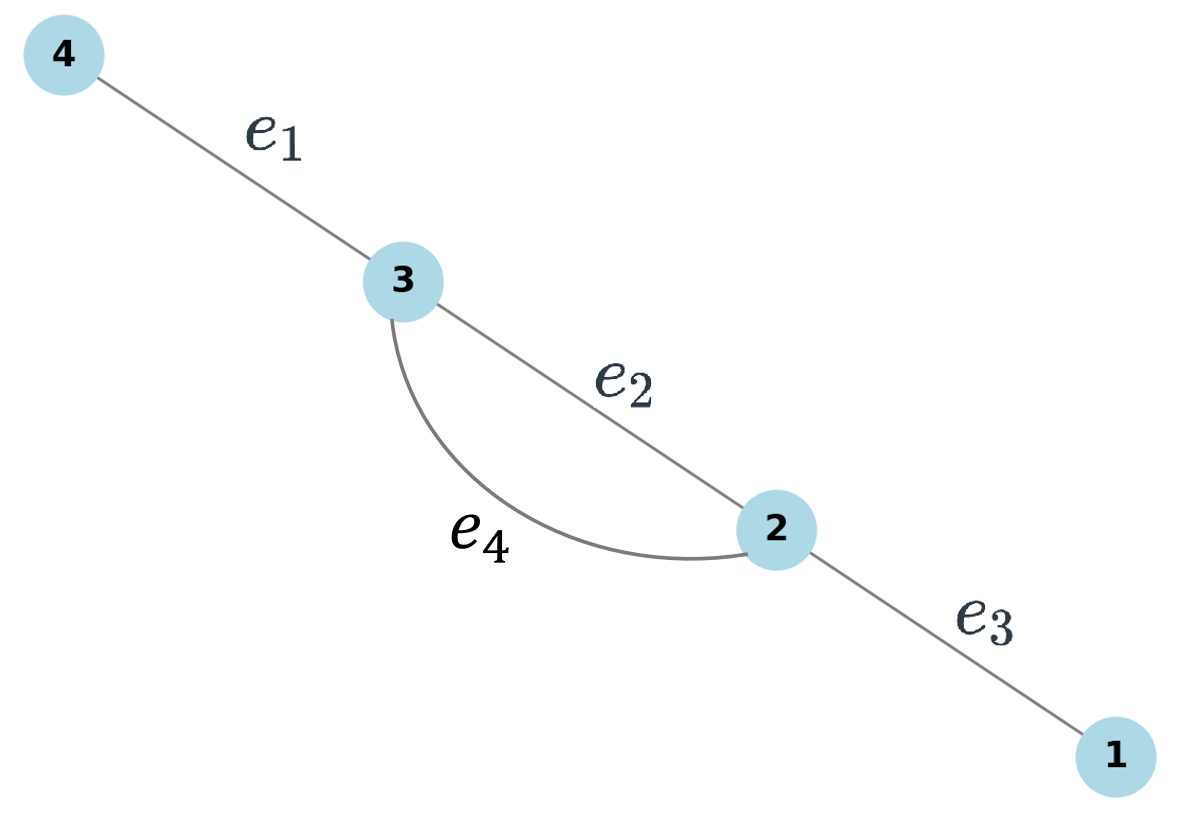

vertices = 1:4;
edges = [3 4; 2 3; 1 2; 3 2];
G_A = HW5P11_construct_graph(vertices, edges, 'Graph_A');
disp(G_A.adj_mat)

     0     1     0     0
     1     0     2     0
     0     2     0     1
     0     0     1     0



disp(G_A.inc_mat)

     0     0     1     0
     0     1     1     1
     1     1     0     1
     1     0     0     0



disp(G_A.degrees)

     1
     3
     3
     1



disp(G_A)

         name: 'Graph_A'
     vertices: [4×1 double]
            n: 4
        edges: [4×2 double]
            m: 4
      adj_mat: [4×4 double]
      inc_mat: [4×4 double]
      degrees: [4×1 double]
       simple: 0
    has_cycle: 1
    connected: 1
     eulerian: 0
         tree: 0
    bipartite: 1



**B**

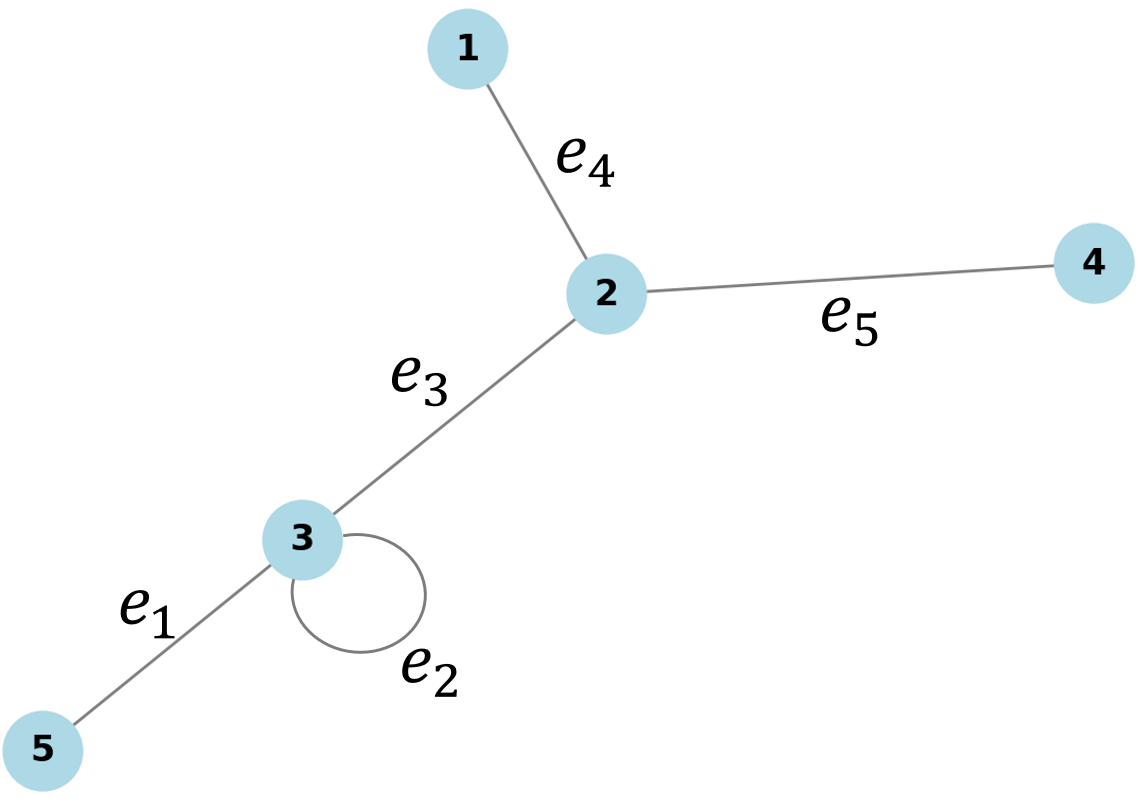

vertices = 1:5;
edges = [5 3; 3 3; 3 2; 2 1; 2 4];
G_B = HW5P11_construct_graph(vertices, edges, 'Graph_B');
disp(G_B.adj_mat)

     0     1     0     0     0
     1     0     1     1     0
     0     1     1     0     1
     0     1     0     0     0
     0     0     1     0     0



disp(G_B.inc_mat)

     0     0     0     1     0
     0     0     1     1     1
     1     1     1     0     0
     0     0     0     0     1
     1     0     0     0     0



disp(G_B.degrees)

     1
     3
     3
     1
     1



disp(G_B)

         name: 'Graph_B'
     vertices: [5×1 double]
            n: 5
        edges: [5×2 double]
            m: 5
      adj_mat: [5×5 double]
      inc_mat: [5×5 double]
      degrees: [5×1 double]
       simple: 0
    has_cycle: 1
    connected: 1
     eulerian: 0
         tree: 0
    bipartite: 0



**C**

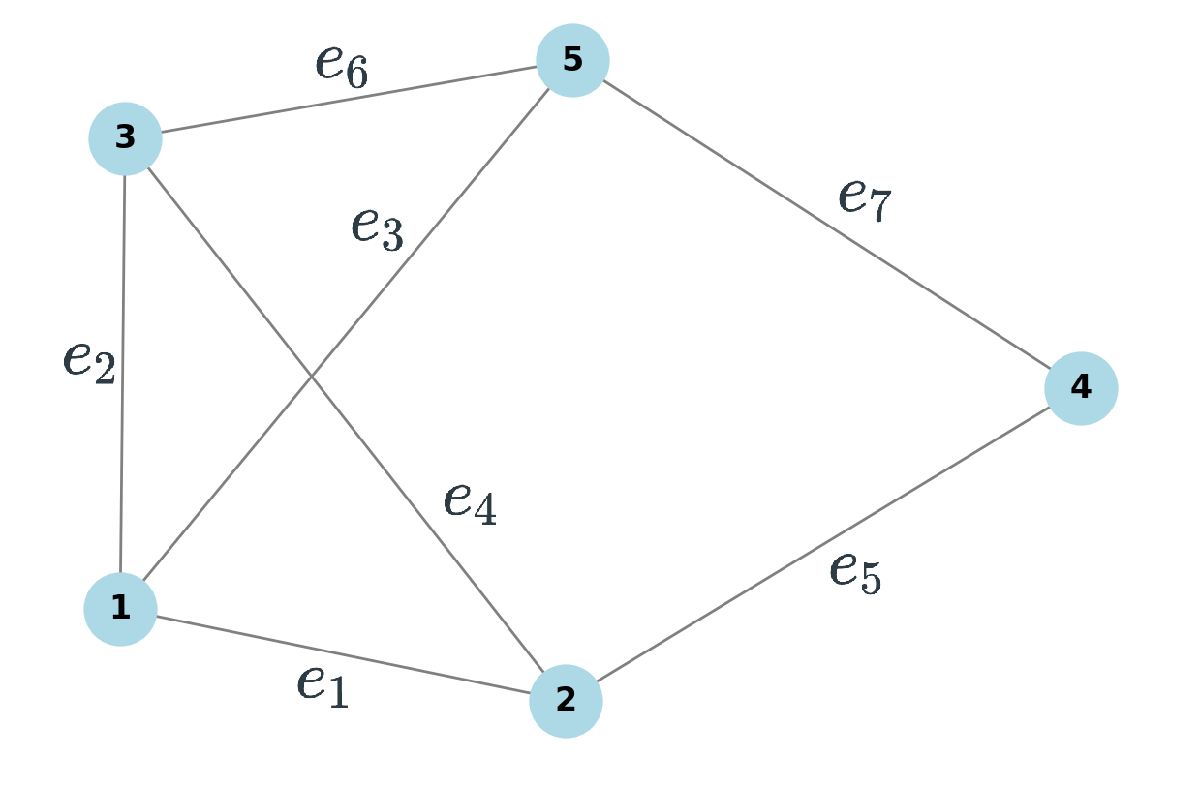

vertices = 1:5;
edges = [1 2; 1 3; 1 5; 2 3; 2 4; 3 5; 4 5];
G_C = HW5P11_construct_graph(vertices, edges, 'Graph_C');
disp(G_C.adj_mat)

     0     1     1     0     1
     1     0     1     1     0
     1     1     0     0     1
     0     1     0     0     1
     1     0     1     1     0



disp(G_C.inc_mat)

     1     1     1     0     0     0     0
     1     0     0     1     1     0     0
     0     1     0     1     0     1     0
     0     0     0     0     1     0     1
     0     0     1     0     0     1     1



disp(G_C.degrees)

     3
     3
     3
     2
     3



disp(G_C)

         name: 'Graph_C'
     vertices: [5×1 double]
            n: 5
        edges: [7×2 double]
            m: 7
      adj_mat: [5×5 double]
      inc_mat: [5×7 double]
      degrees: [5×1 double]
       simple: 1
    has_cycle: 1
    connected: 1
     eulerian: 0
         tree: 0
    bipartite: 0



**D**

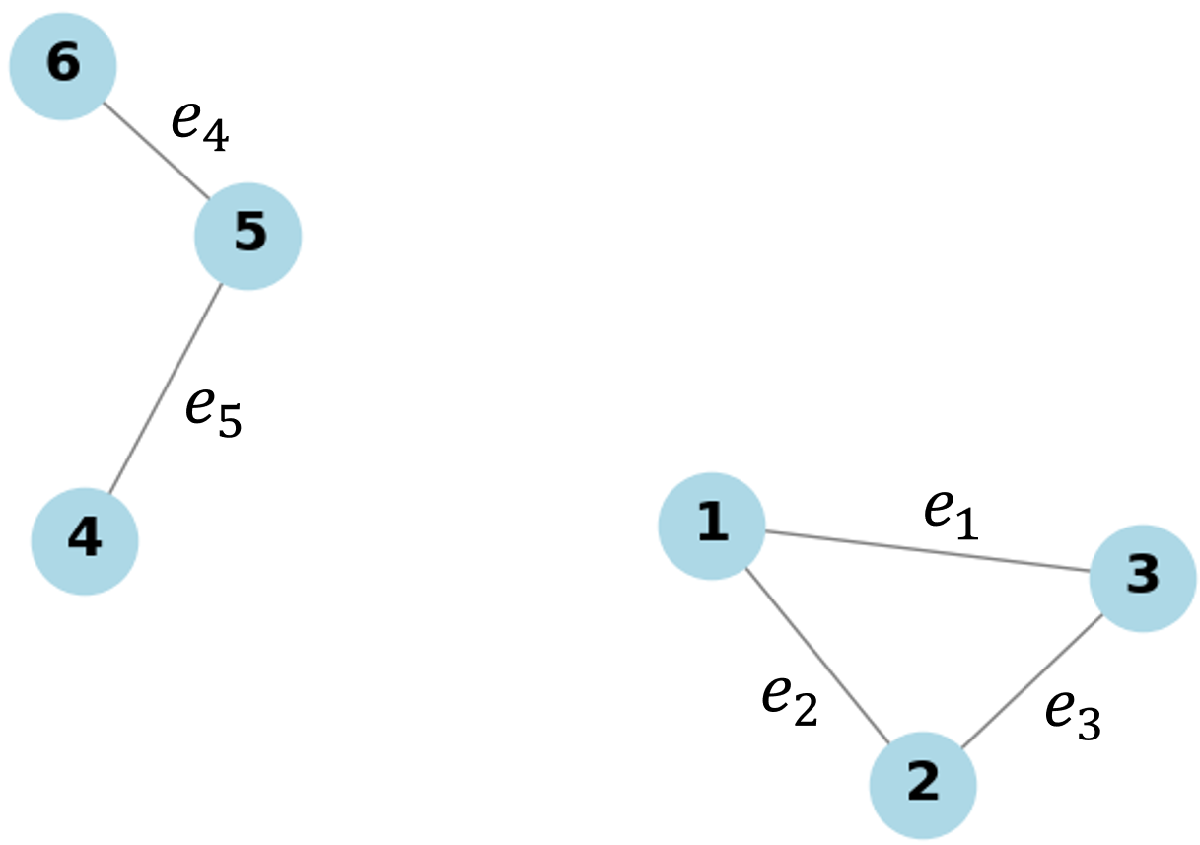

vertices = 1:6;
edges = [1 3; 1 2; 2 3; 6 5; 5 4];
G_D = HW5P11_construct_graph(vertices, edges, 'Graph_D');
disp(G_D.adj_mat)

     0     1     1     0     0     0
     1     0     1     0     0     0
     1     1     0     0     0     0
     0     0     0     0     1     0
     0     0     0     1     0     1
     0     0     0     0     1     0



disp(G_D.inc_mat)

     1     1     0     0     0
     0     1     1     0     0
     1     0     1     0     0
     0     0     0     0     1
     0     0     0     1     1
     0     0     0     1     0



disp(G_D.degrees)

     2
     2
     2
     1
     2
     1



disp(G_D)

         name: 'Graph_D'
     vertices: [6×1 double]
            n: 6
        edges: [5×2 double]
            m: 5
      adj_mat: [6×6 double]
      inc_mat: [6×5 double]
      degrees: [6×1 double]
       simple: 1
    has_cycle: 1
    connected: 0
     eulerian: 0
         tree: 0
    bipartite: 0



**E**

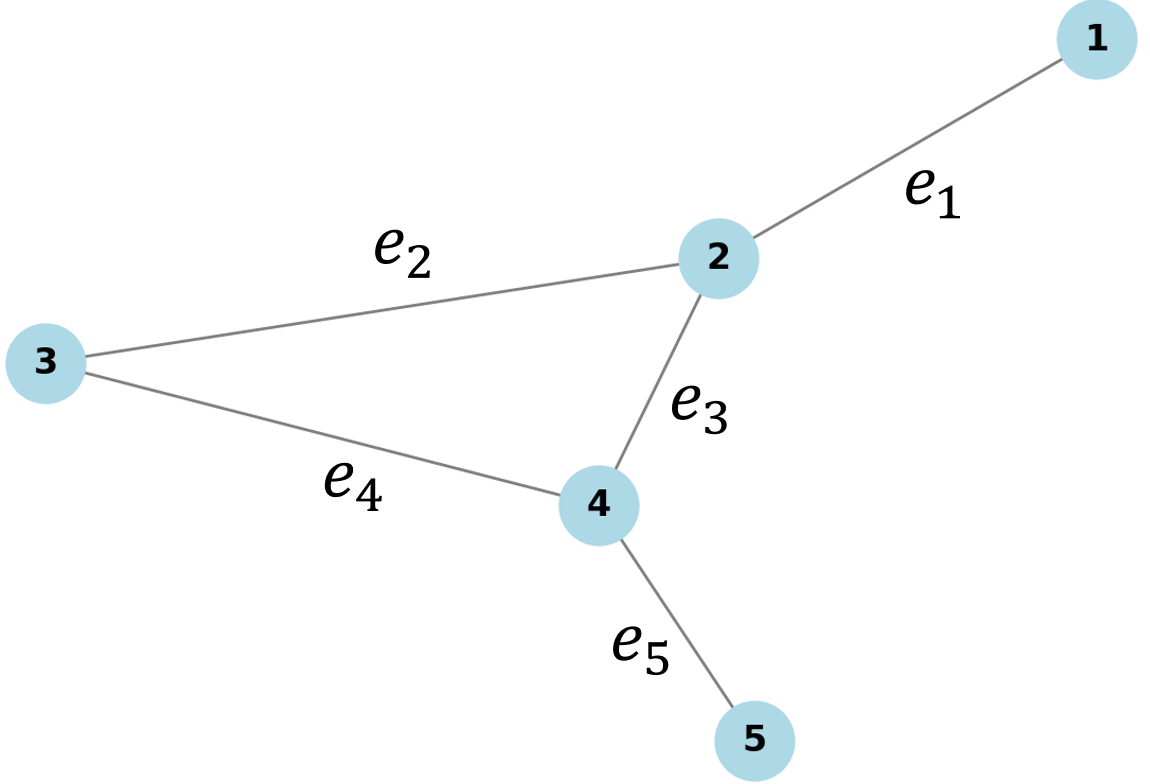

vertices = 1:5;
edges = [1 2; 2 3; 2 4; 3 4; 4 5];
G_E = HW5P11_construct_graph(vertices, edges, 'Graph_E');
disp(G_E.adj_mat)

     0     1     0     0     0
     1     0     1     1     0
     0     1     0     1     0
     0     1     1     0     1
     0     0     0     1     0



disp(G_E.inc_mat)

     1     0     0     0     0
     1     1     1     0     0
     0     1     0     1     0
     0     0     1     1     1
     0     0     0     0     1



disp(G_E.degrees)

     1
     3
     2
     3
     1



disp(G_E)

         name: 'Graph_E'
     vertices: [5×1 double]
            n: 5
        edges: [5×2 double]
            m: 5
      adj_mat: [5×5 double]
      inc_mat: [5×5 double]
      degrees: [5×1 double]
       simple: 1
    has_cycle: 1
    connected: 1
     eulerian: 0
         tree: 0
    bipartite: 0



**F**

vertices = 1;
edges = [];
G_F = HW5P11_construct_graph(vertices, edges, 'Graph_F');
disp(G_F.adj_mat)

     0



disp(G_F.inc_mat)
disp(G_F.degrees)

     0



disp(G_F)

         name: 'Graph_F'
     vertices: 1
            n: 1
        edges: []
            m: 0
      adj_mat: 0
      inc_mat: [1×0 double]
      degrees: 0
       simple: 1
    has_cycle: 0
    connected: 1
     eulerian: 1
         tree: 1
    bipartite: 1

